%% Machine Learning
% Lab 3: Logistic Regression (Linear case)
% --- Admit students to university ---
%{
In this part of the exercise, you will build a logistic regression model to
predict whether a student gets admitted into a university.
Suppose that you are the administrator of a university department and
you want to determine each applicant's chance of admission based on their
results on two exams. You have historical data from previous applicants
that you can use as a training set for logistic regression. For each training
example, you have the applicant's scores on two exams and the admissions
decision.
%}

%% Initialization
clear ; close all; clc

%% Load Data
%  The first two columns contains the exam scores and the third column
%  contains the label.

%Data parsing
data = load('ex2data1.txt');
X = data(:, [1, 2]); % x1: exam 1 point; x2: exam 2 point
Y = data(:, 3);      % Passed or Failed

% Print out first 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) Y(1:10,:)]');

 x = [35 78], y = 0 
 x = [30 44], y = 0 
 x = [36 73], y = 0 
 x = [60 86], y = 1 
 x = [79 75], y = 1 
 x = [45 56], y = 0 
 x = [61 97], y = 1 
 x = [75 47], y = 1 
 x = [76 87], y = 1 
 x = [84 44], y = 1 


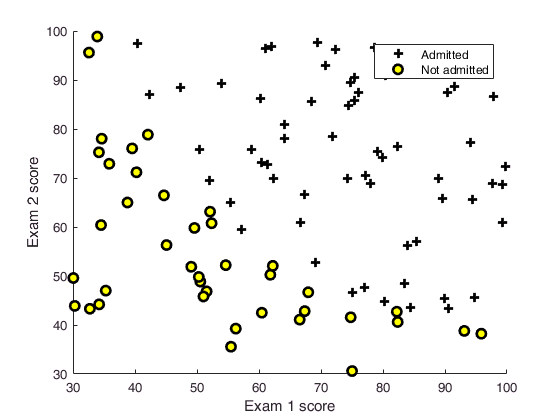

%% Plotting
%  We start the exercise by first plotting the data to understand the 
%  the problem we are working with.

%Plotting data with 
% + indicating (y = 1) examples and 
% o indicating (y = 0) examples
     
plotData(X, Y);
% Put some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

%% Compute Cost and Gradient
% m: number of samples
% n: number of features
[m, n] = size(X);
% Additional Bias
X = [ones(m, 1) X];

% Initialize Weights
initial_w = zeros(n + 1, 1);

% Compute and display initial cost and gradient
[C, grad] = costFunction(initial_w, X, Y);

fprintf('Cost at initial weights (zeros): %f\n', C);

Cost at initial weights (zeros): 0.693147


fprintf('Expected cost (approx): 0.693\n');

Expected cost (approx): 0.693


fprintf('Gradient at initial weights (zeros): \n');

Gradient at initial weights (zeros): 


fprintf(' %f \n', grad);

 -0.100000 
 -12.009217 
 -11.262842 


fprintf('Expected gradients (approx):\n -0.1000\n -12.0092\n -11.2628\n');

Expected gradients (approx):
 -0.1000
 -12.0092
 -11.2628



% Compute and display cost and gradient with non-zero theta
test_w = [-24; 0.2; 0.2];
[C, grad] = costFunction(test_w, X, Y);

fprintf('\nCost at test weights: %f\n', C);


Cost at test weights: 0.218330


fprintf('Expected cost (approx): 0.218\n');

Expected cost (approx): 0.218


fprintf('Gradient at test weights: \n');

Gradient at test weights: 


fprintf(' %f \n', grad);

 0.042903 
 2.566234 
 2.646797 


fprintf('Expected gradients (approx):\n 0.043\n 2.566\n 2.647\n');

Expected gradients (approx):
 0.043
 2.566
 2.647


%% === Optimizing using fminunc ===

%  In this exercise, you will use a built-in function (fminunc) to find the
%  optimal parameters weights.

%  Set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return weights and the cost 
[w, C] = fminunc(@(t)(costFunction(t, X, Y)), initial_w, options);


Local minimum possible.

fminunc stopped because the final change in function value relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>




% Print weights to screen
fprintf('Cost at weights found by fminunc: %f\n', C);

Cost at weights found by fminunc: 0.203506


fprintf('Expected cost (approx): 0.203\n');

Expected cost (approx): 0.203


fprintf('weights: \n');

weights: 


fprintf(' %f \n', w);

 -24.932758 
 0.204406 
 0.199616 


fprintf('Expected weights (approx):\n');

Expected weights (approx):


fprintf(' -25.161\n 0.206\n 0.201\n');

 -25.161
 0.206
 0.201


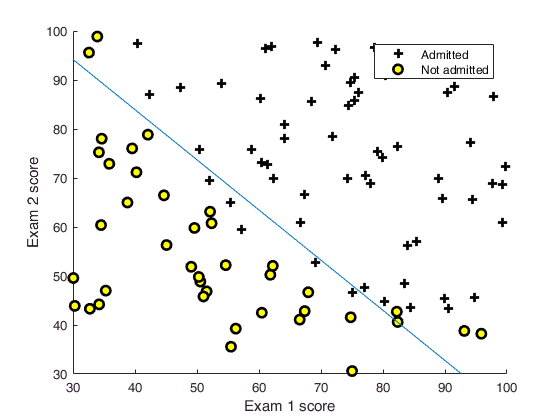

%% Plot Boundary
plotDecisionBoundary(w, X, Y);

% Put some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

%% ============== Part 4: Predict and Accuracies ==============
%  After learning the parameters, you'll like to use it to predict the outcomes
%  on unseen data. In this part, you will use the logistic regression model
%  to predict the probability that a student with score 45 on exam 1 and 
%  score 85 on exam 2 will be admitted.
%
%  Furthermore, you will compute the training and test set accuracies of 
%  our model.

prob = sigmoid([1 45 85] * w);
fprintf(['For a student with scores 45 and 85, we predict an admission ' ...
         'probability of %f\n'], prob);

For a student with scores 45 and 85, we predict an admission probability of 0.774321


fprintf('Expected value: 0.775 +/- 0.002\n\n');

Expected value: 0.775 +/- 0.002




% Compute accuracy on our training set
p = predict(w, X);

fprintf('Train Accuracy: %f\n', mean(double(p == Y)) * 100);

Train Accuracy: 89.000000


fprintf('Expected accuracy (approx): 89.0\n');

Expected accuracy (approx): 89.0


fprintf('\n');